# Line plot example

## Load data file 

Use the load function. File name: historicalQuotes_AAPLvsIBM.mat

load('historicalQuotes_AAPLvsIBM.mat');

## Create Figure object

Use function figure 

fig1 = figure();

## Plot closing price

Use the plot function to create chart/line objects and plot the closing price for AAPL and IBM. Also get the handle to the axes object using the CurrentAxes proerty of the figure.

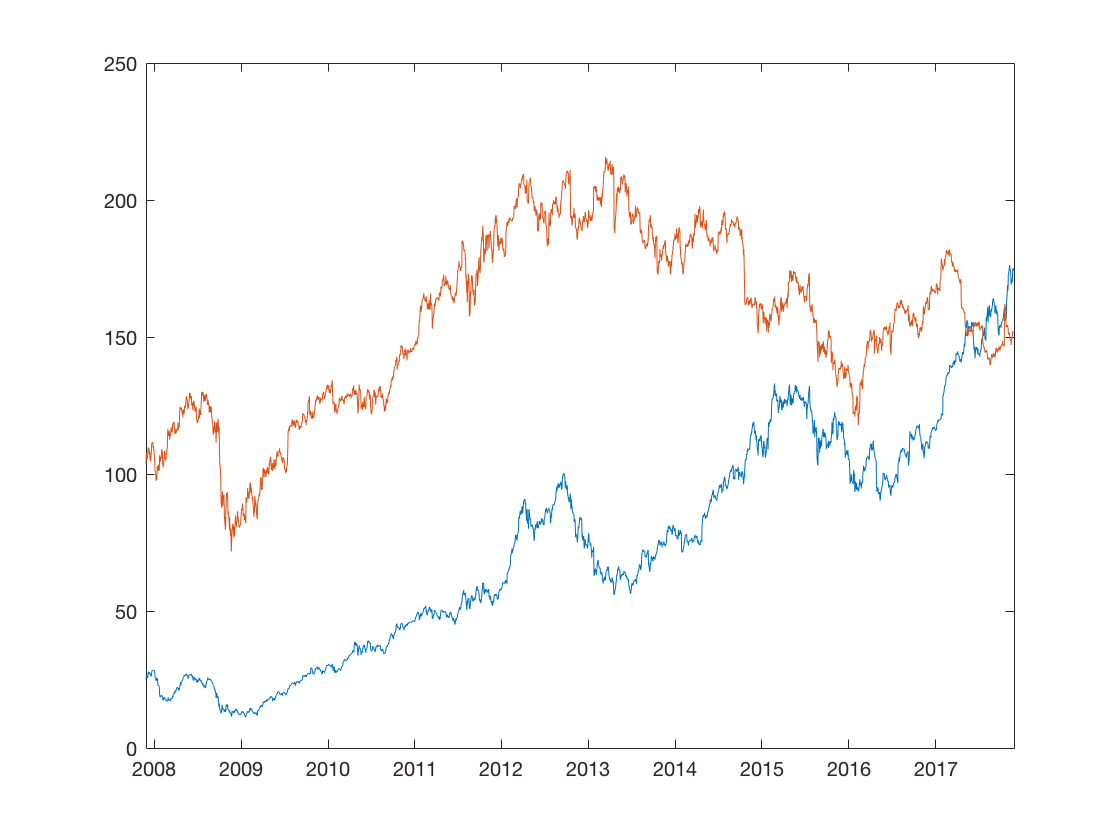

p1 = plot(AAPLt, AAPLcp);
hold on; 
p2 = plot(IBMt, IBMcp);
hold off;

ax1 = fig1.CurrentAxes;

## Modify axes properties

Add title, axis labels

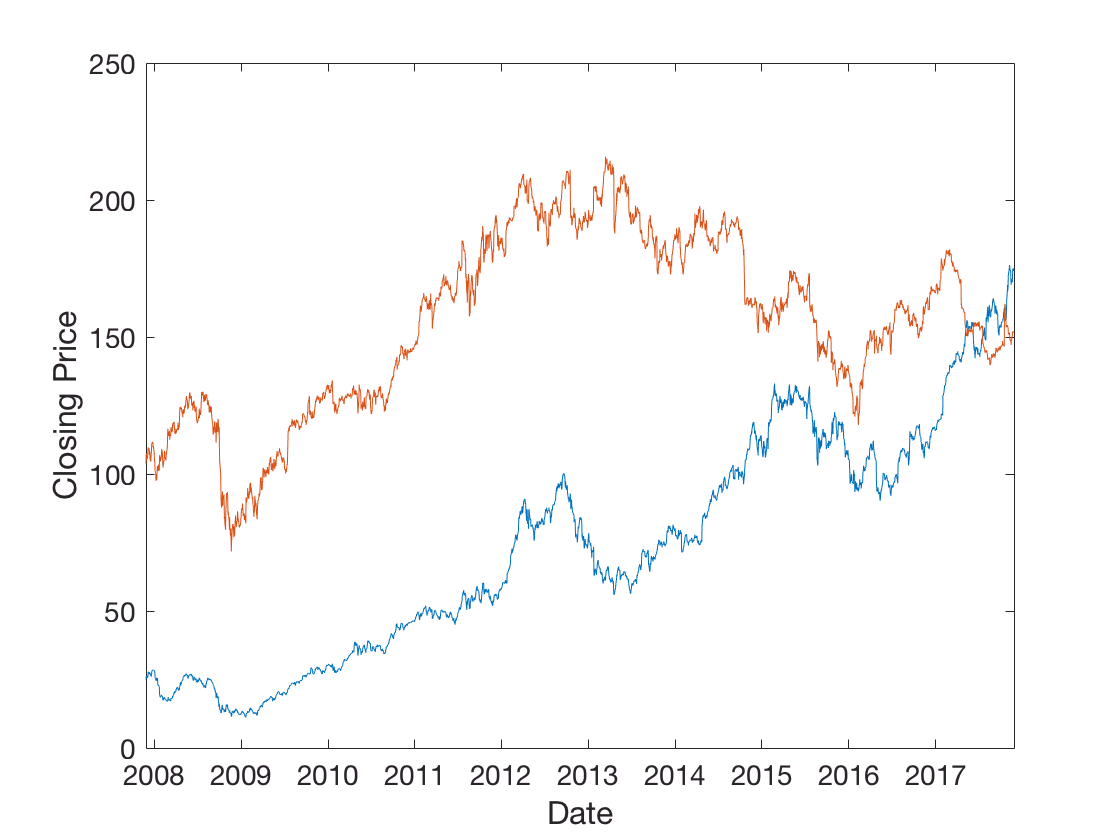

ax1.XLabel.String = 'Date';
ax1.YLabel.String = 'Closing Price';
ax1.FontSize = 14;
ax1.XLabel.FontSize = 16;
ax1.YLabel.FontSize = 16;

## Modify line properties

Increase fontsize, linewidth

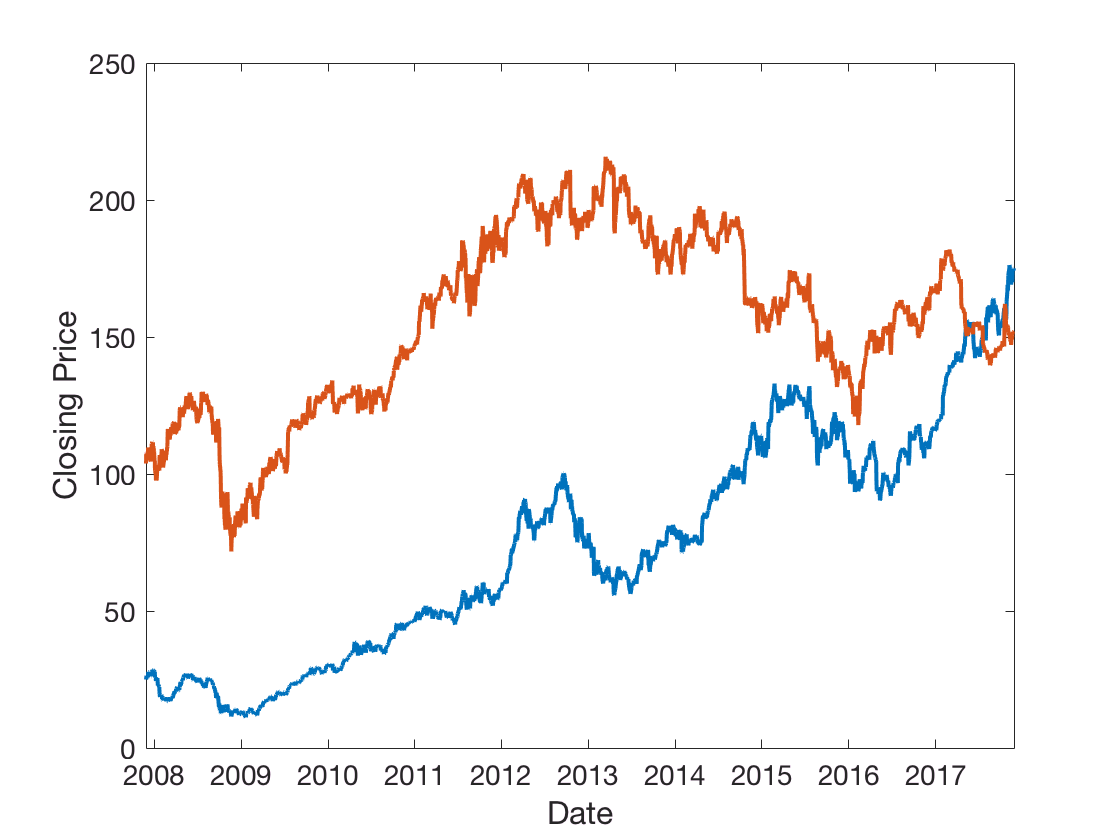

p1.LineWidth = 2;
p2.LineWidth = 2;

## Add Legend

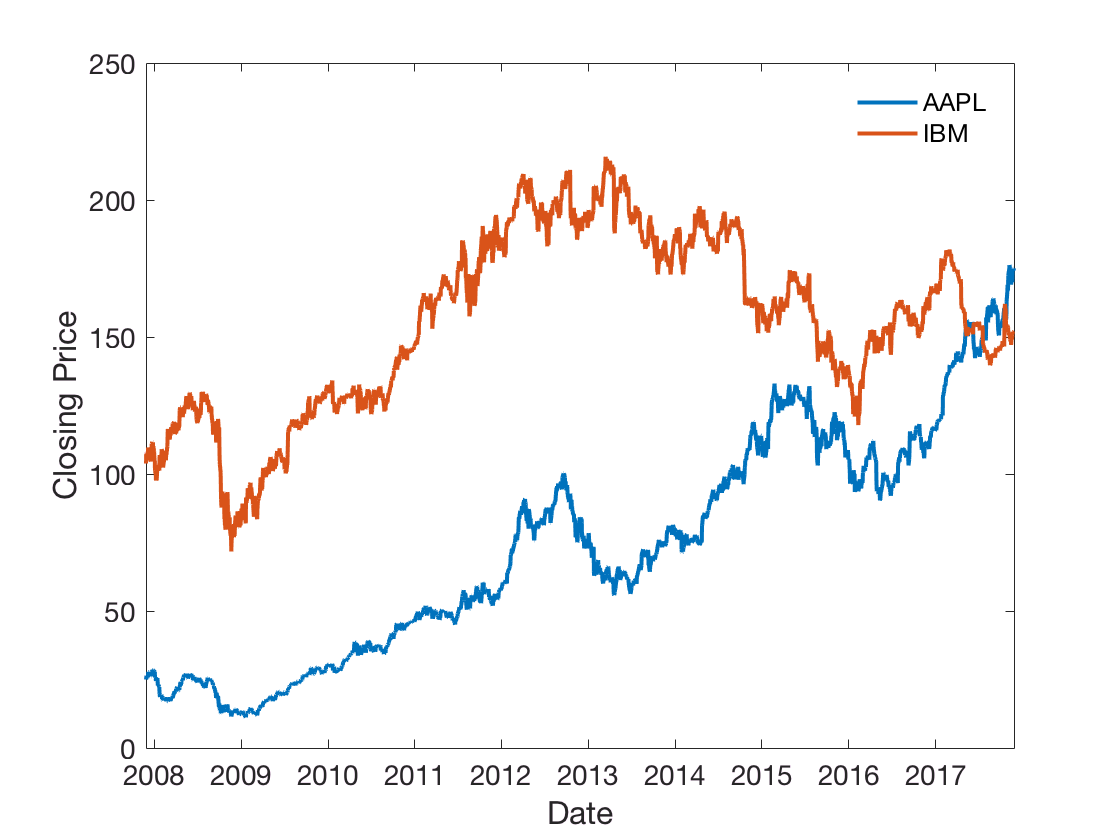

legend([p1, p2], 'AAPL', 'IBM');
legend('boxoff');

## Modify range of x axis

Zoom in on the crossing in 2017 and change appearance using the function xtickformat

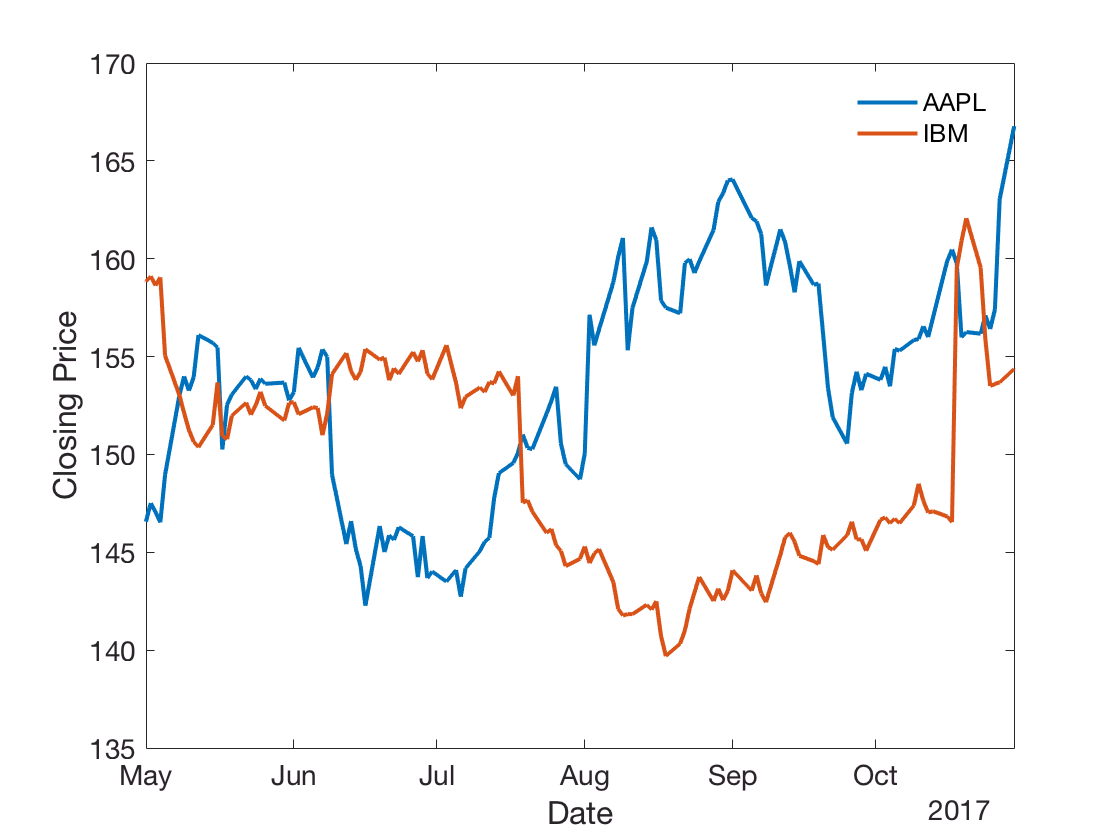

ax1.XLim = datetime(2017, [5 10], [1 30]);
xtickformat('MMM')

## Add lines

Add lines for high and low price of the day and change their color properties

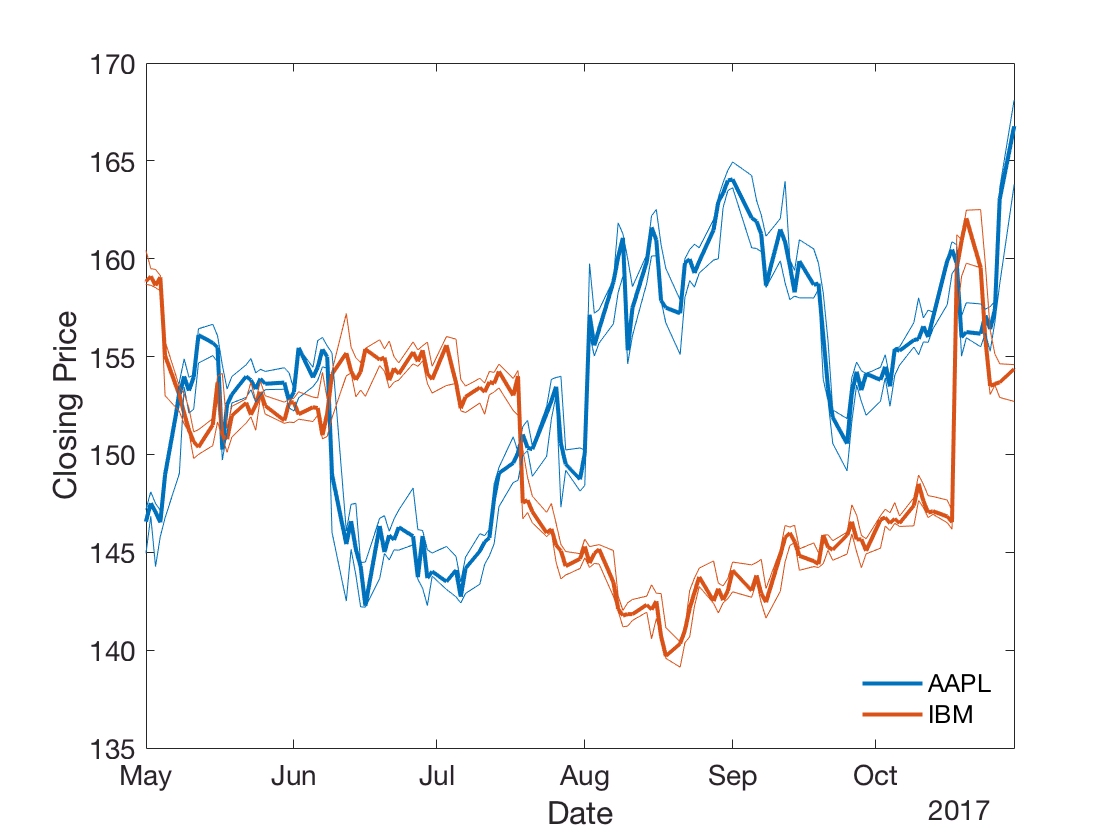

color1 = [0 0.4470 0.7410];
color2 = [0.8500 0.3250 0.0980];
hold on;
p3 = plot(AAPLt, AAPLhp, AAPLt, AAPLlp);
p4 = plot(IBMt, IBMhp, IBMt, IBMlp);
hold off
p3(1).Color = color1;
p4(1).Color = color2;
p3(2).Color = color1;
p4(2).Color = color2;
legend([p1, p2], 'AAPL', 'IBM', 'Location', 'best');

## Modify x axis range 

Zoom in on July 2017

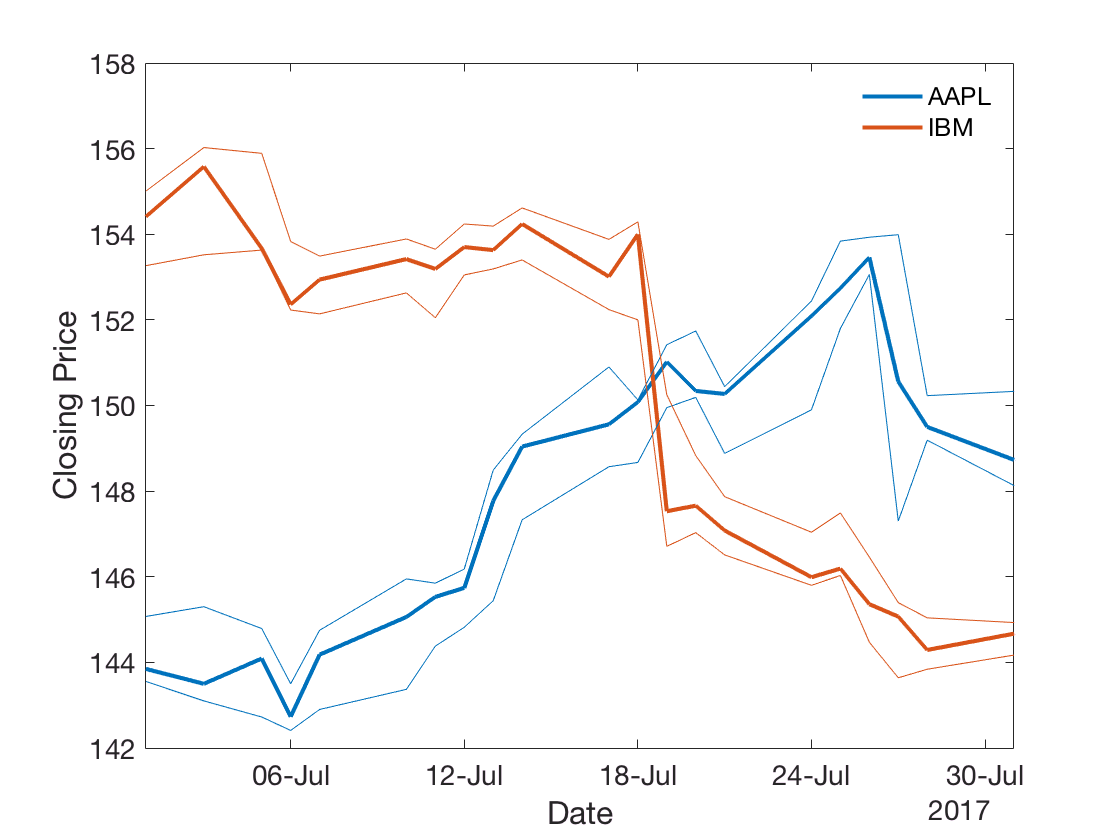

ax1.XLim = datetime(2017, 7, [1 31]);
xtickformat('dd-MMM')
legend([p1, p2], 'AAPL', 'IBM', 'Location', 'best');

## Change line properties

Add markers and change line style

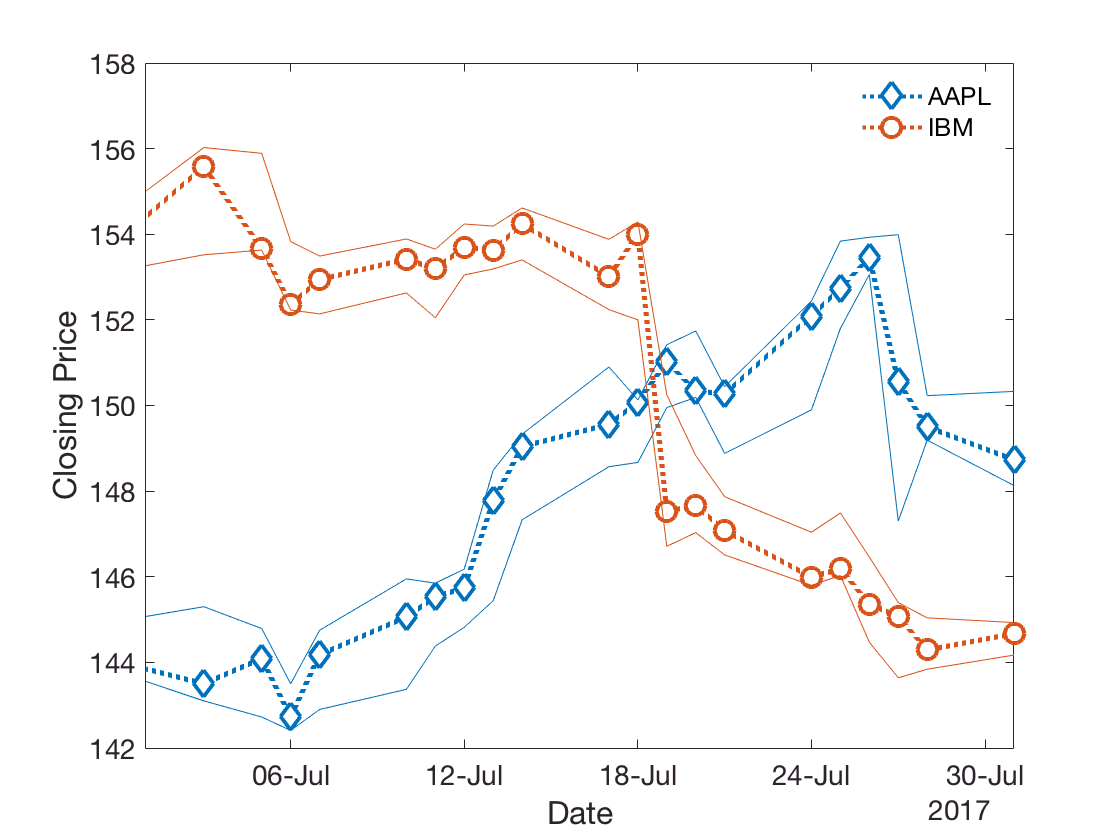

p1.LineStyle = ':';
p1.Marker = 'd';
p1.MarkerSize = 10;
p1.MarkerFaceColor = 'auto';
p2.LineStyle = ':';
p2.Marker = 'o';
p2.MarkerSize = 10;
p2.MarkerFaceColor = 'auto';